Ara podem crear dades artificials i ajustar un model de SVM

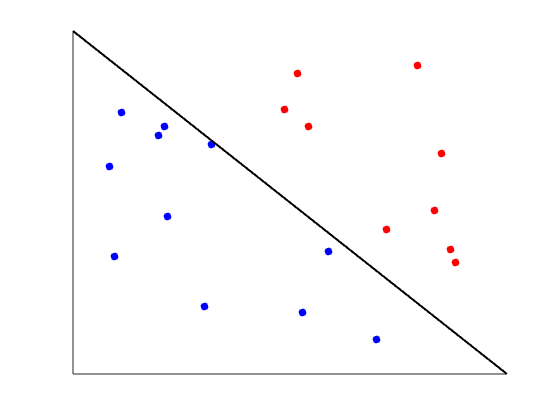

% Define the number of points
numPoints = 20;

% Generate random x and y coordinates for the points
% Set the seed value
seed = 12;
%seed = 1;
% Set the random number generator seed
rng(seed);

points = rand([numPoints, 2]);
w = [1,1];
b = -1;
[points_classes,class1,class2] = classifyPoints(w,b,points);

plotSVM(points, w, b)

disp(min(abs(w*points' + b)/norm(w)));

    0.0096



    12

    18

    19



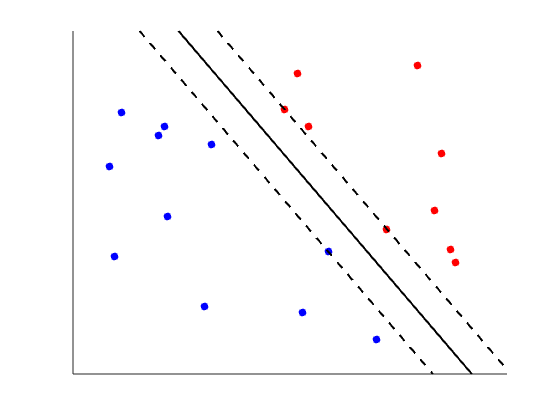

% Hard margin
[wo, bo] = trainSVM(points, points_classes);
plotSVM(points, wo, bo)

disp(min(abs(wo*points' + bo)/norm(wo)));

    0.0893



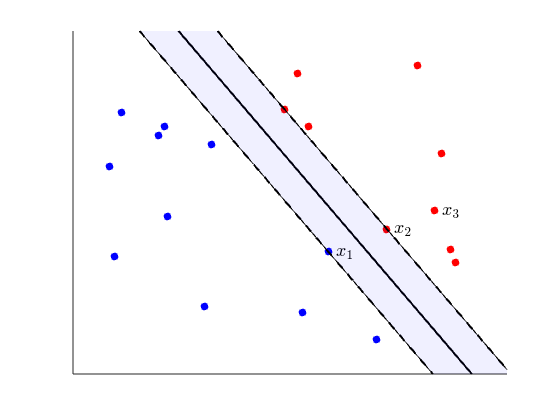

% Soft margin
% Margin violation penalty
C = 1;
[wos, bos, xi] = trainSoftSVM(points, points_classes, C);
plotSoftSVM(points,points_classes,class1,class2, wo, bo)